# Cvičení 3 - B2M31AEDA

## Nahrání dat

Dejte si pozor na to, aby jste byli v MATLABu ve složce, kde máte umístěn soubor s daty (data.csv), nebo máte složku, ve které je soubor s daty, přidanou do cesty MATLABu (Matlab Path).

close all; clear; clc; addpath(genpath(fullfile([pwd '\Uni' '\grad' '\AEDA' '\week03' '\sem'])))
table = readtable('data.csv','ReadVariableNames',true);

Prohlédněte si data - hodnoty a jejich popisky - přístupem ke sloupcům v tabulce:

HC = table.VOT(ismember(table.group,'HC'));
PD = table.VOT(ismember(table.group,'PD'));
X = table.VOT(ismember(table.group,'?'));

## 1. Vizualizace a výpočet Cohenova d

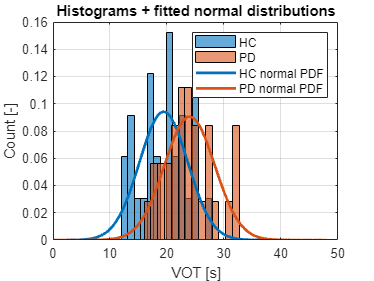

HCmean = mean(HC);
HCstd = std(HC);
PDmean = mean(PD);
PDstd = std(PD);

xRange = linspace(0, 2*max(HCmean, PDmean));
HCpdf = normpdf(xRange, HCmean, HCstd);
PDpdf = normpdf(xRange, PDmean, PDstd);

figure(1)
HChist = histogram(HC, 14, 'Normalization', 'pdf', 'FaceColor', '#0072BD');
hold on
PDhist = histogram(PD, 14, 'Normalization', 'pdf', 'FaceColor', '#D95319');
plot(xRange, HCpdf, 'Color', HChist.FaceColor, 'LineWidth', 2)
plot(xRange, PDpdf, 'Color', PDhist.FaceColor, 'LineWidth', 2)
hold off
grid on
xlabel('VOT [s]')
ylabel('Count [-]')
legend('HC', 'PD', 'HC normal PDF', 'PD normal PDF')
title('Histograms + fitted normal distributions')

**Otázky:**

- *Jak byste pouhým okem zhodnotili efekt skupin, tj. rozdíly mezi skupinami, viditelné na vaší vizualizaci?*

Již pouhým okem je vidět, že skupinu pacientů PD (postiženou Parkinsonovou nemocí) lze na základě DDK testu zřetelně odlišit od skupiny HC (zdravých subjektů). Efekt skupin (rozřazených na základě DDK testu) lze tak posoudit jako silný.

sigma_P = sqrt(((length(HC)*HCstd^2+(length(PD)-1)*PDstd^2))/(length(HC)+length(PD)+2));
d = abs(HCmean-PDmean)/sigma_P;
fprintf('Cohen''s d = %.2f', d)

Cohen's d = 1.08

**Otázky:**

- *Jaký silný je efekt mezi analyzovanými skupinami?*

Na základě Cohenova parametru $d$ soudíme, že efekt mezi analyzovanými skupinami je vskutku *silný*. Pro slabé efekty se hodnota pohybuje kolem $0\ldotp 2$ a pro střední kolem $0\ldotp 5$.

## 2. Odhad parametrů normálního rozložení a výpočet populační CDF

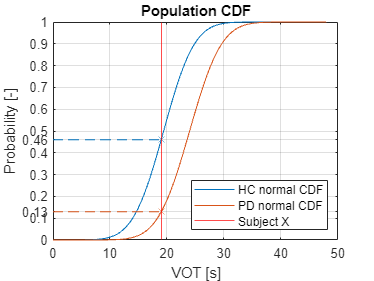

HCcdf = cdf('Normal', xRange, HCmean, HCstd);
PDcdf = cdf('Normal', xRange, PDmean, PDstd);

iX = find(diff(sign(xRange-X)));
iXrange = max(1,iX-1):min(length(xRange),iX+1);
yX_HC = interp1(xRange(iXrange), HCcdf(iXrange), X);
yX_PD = interp1(xRange(iXrange), PDcdf(iXrange), X);

figure(5)
plot(xRange, HCcdf)
hold on
plot(xRange, PDcdf)
xline(X, '-r')
plot(X, yX_HC, 'x', 'Color', HChist.FaceColor)
plot(X, yX_PD, 'x', 'Color', PDhist.FaceColor)
plot([0 X], [1 1]*yX_HC, '--', 'Color', HChist.FaceColor)
plot([0 X], [1 1]*yX_PD, '--', 'Color', PDhist.FaceColor)
hold off
grid on
yticks(sort([yticks round(yX_HC,2) round(yX_PD,2)]))
xlabel('VOT [s]')
ylabel('Probability [-]')
legend('HC normal CDF', 'PD normal CDF', 'Subject X', 'Location', 'southeast')
title('Population CDF')

**Otázky:**

- *Přiřadili byste subjekt X spíše do skupiny HC, do skupiny PD nebo byste ho nezařadili do ani do jedné?*

Subjekt X bychom zařadili spíše do skupiny HC, neboť kumulativní pravděpodobnost pro jeho hodnotu CDF vychází výrazně vyšší právě pro tuto skupinu.

## 3. Bootstrapping

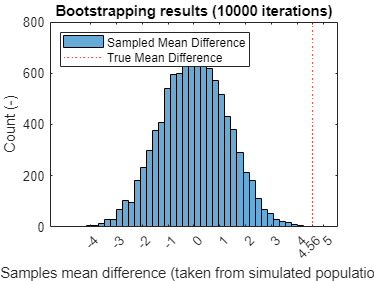

meanDiff = PDmean-HCmean;
alpha = 0.05;

population = cat(1, HC, PD);
popLength = length(population);
HClength = length(HC);
PDlength = length(PD);

Nsamples = 1e4;
sampledMeanDiff = zeros(Nsamples, 1);
for sample = 1:Nsamples
    sample1 = population(randperm(popLength, HClength));
    sample2 = population(~ismember(population, sample1),:);
    sampledMeanDiff(sample) = mean(sample1)-mean(sample2);
end

figure(6)
histogram(sampledMeanDiff, 40)
hold on
xline(meanDiff, ':r')
hold off
xticks(sort([xticks round(meanDiff,2)]))
xlim([-abs(meanDiff)-1 abs(meanDiff)+1])
xlabel('Samples mean difference (taken from simulated population)')
ylabel('Count (-)')
legend('Sampled Mean Difference', 'True Mean Difference', 'Location', 'northwest')
title(['Bootstrapping results (' num2str(Nsamples) ' iterations)'])


pBootstrap = length(find(abs(sampledMeanDiff) >= meanDiff))/Nsamples;
fprintf(['Null hypothesis:\n' ...
    '\tSamples HC and PD come from distributions of equal means.\n' ...
    'Altenative hypothesis:\n' ...
    '\tSamples from HC and PD come from distributions of different means.\n' ...
    'Significance level:\n' ...
    '\t%.2f\n' ...
    'Bootstrapping results:\n' ...
    '\tp = %.5f\n'], alpha, pBootstrap)

Null hypothesis:
	Samples HC and PD come from distributions of equal means.
Altenative hypothesis:
	Samples from HC and PD come from distributions of different means.
Significance level:
	0.05
Bootstrapping results:
	p = 0.00020


Jelikož výsledná $p$-value je nižší nežli nastavená hodnota statistické významností $\alpha$, jsme nuceni nulovou hypotézu zamítnout a lze přijmout hypotézu alternativní, tj. že vzorky HC a PD pochází z populací s různou střední hodnotou. Potvrdili jsme si tak pomocí techniky *bootstrappingu* naše prvotní pozorování odlišností na základě odhadovaných distribucí.

[h,pTtest,~,stats] = ttest2(HC, PD, 'Alpha', alpha);
fprintf(['T-test results:\n' ...
    '\tp = %.5f\n' ...
    'Decision:\n' ...
    '\t%d (null hypothesis rejected)\n' ...
    'Report:\n' ...
    '\tThe %d subjects from the group PD affected by Parkinson''s disease (M = %.2f, SD = %.2f)\n' ...
    '\tcompared to the %d subjects from the healthy control group HC (M = %.2f, SD = %.2f)\n' ...
    '\tdemonstrated significantly higher peak values of VOT during the DDK test,\n' ...
    '\tt(%d) = %.2f, p < 0.001.\n'], ...
    pTtest, h, PDlength, PDmean, PDstd, HClength, HCmean, HCstd, HClength+PDlength-1, stats.tstat)

T-test results:
	p = 0.00016
Decision:
	1 (null hypothesis rejected)
Report:
	The 30 subjects from the group PD affected by Parkinson's disease (M = 23.97, SD = 4.40)
	compared to the 29 subjects from the healthy control group HC (M = 19.41, SD = 4.24)
	demonstrated significantly higher peak values of VOT during the DDK test,
	t(58) = -4.05, p < 0.001.


- **Obrázek s bootstrappingovým histogramem a skutečnými hodnotami rozdílů středních hodnot skupin.**

- **Slovní znění vašich hypotéz, vaše nastavení hladiny statistické významnosti a vypočtená hodnota *****p*****-value z bootstrappingu.**

- **Korektní report výsledku t-testu. **

- **Velmi stručná interpretace výsledků.**

- **Porovnání výsledků bootstrappingu s výsledky funkce ttest2.**

*Porovnání výsledků: *Přestože výsledná $p$-value testů se mírně liší, na rozhodnutí rozdíl nemá vliv. Můžeme tak usoudit, že (minimálně v případě těchto vzorků) jsou obě techniky validním přístupem.

## Nepovinný bonus

% Váš kód
% Nápověda: Bayesova věta

